%% 衝突判定ベンチマーク
clear; clc; close all;

% テストケース定義
planesList = [1000,1000,1000];
raysList = [10000,100000,1000000];


利用可能な手法を確認

methods = {'Vectorized', 'Parfor', 'GPU', 'Batch'};
detectors = {};
detectors{1} = VectorizedCollisionDetector();
detectors{2} = ParforCollisionDetector();
detectors{3} = GPUCollisionDetector();
detectors{4} = BatchCollisionDetector();


% 結果格納用
results = zeros(length(planesList), length(methods));
validMethods = ~cellfun(@isempty, detectors);


実行時間の詳細表

fprintf('【実行時間】\n');

【実行時間】


fprintf('%-8s %-8s %-12s', '平面数', 'レイ数', '総テスト数');

平面数      レイ数      総テスト数       

for j = 1:length(methods)
    fprintf('%-12s ', methods{j});
end

Vectorized   Parfor       GPU          Batch        

fprintf('\n');
fprintf('----------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------



for i = 1:length(planesList)
    collision = [];
    numPlanes = planesList(i);
    numRays = raysList(i);
    
    % データ生成
    planeGen = RandomPlaneGenerator(numPlanes);
    rayGen = RayGenerator(numRays);
    
    fprintf('%-8d %-8d %-12d', numPlanes, numRays, numPlanes * numRays);
    
    % 各手法で測定
    for j = 1:length(methods)
        if ~isempty(detectors{j})
            [collision(j,:,:), time] = detectors{j}.detect(planeGen, rayGen);
            results(i, j) = time;
            fprintf('%-12.4f ', time);
        else
            results(i, j) = NaN;
            fprintf('%-12s ', '---');
        end
    end
    fprintf('\n');

    % 正答率計算
    for j = 1:length(methods)
        correctRatio(i,j) = sum(collision(j,:,:) == collision(1,:,:),"all")/numel(collision(1,:,:));
    end
end

1000     10000    10000000    

0.2818       3.5326       1.4794       0.4260       

1000     100000   100000000   

2.3352       43.4153      2.0133       4.2302       

1000     1000000  1000000000  

33.7150      466.1474     14.1913      47.7851      


fprintf('\n');

スピードアップ表

if validMethods(1)  % Serialが利用可能な場合
    fprintf('【スピードアップ (Serial基準)】\n');
    fprintf('%-8s %-8s %-12s', '平面数', 'レイ数', '総テスト数');
    for j = 2:length(methods)
        if validMethods(j)
            fprintf('%-12s ', methods{j});
        end
    end
    fprintf('\n');
    fprintf('----------------------------------------------------------------------------------\n');
    
    for i = 1:length(planesList)
        numPlanes = planesList(i);
        numRays = raysList(i);
        
        fprintf('%-8d %-8d %-12d', numPlanes, numRays, numPlanes * numRays);
        
        for j = 2:length(methods)
            if validMethods(j)
                speedup = results(i, 1) / results(i, j);
                fprintf('%-12.2fx', speedup);
            end
        end
        fprintf('\n');
    end
    fprintf('\n');
end

【スピードアップ (Serial基準)】


平面数      レイ数      総テスト数       

Parfor       GPU          Batch        

----------------------------------------------------------------------------------


1000     10000    10000000    

0.08        x0.19        x0.66        x

1000     100000   100000000   

0.05        x1.16        x0.55        x

1000     1000000  1000000000  

0.07        x2.38        x0.71        x


% 統計サマリー
fprintf('【統計サマリー】\n');

【統計サマリー】


fprintf('----------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------



% 各手法の平均時間
fprintf('平均実行時間:\n');

平均実行時間:


for j = 1:length(methods)
    if validMethods(j)
        avgTime = mean(results(~isnan(results(:, j)), j));
        fprintf('  %-15s: %10.4f 秒\n', methods{j}, avgTime);
    end
end

  Vectorized     :    12.1106 秒
  Parfor         :   171.0318 秒
  GPU            :     5.8947 秒
  Batch          :    17.4804 秒


fprintf('\n');

% 最速手法の特定
fprintf('各ケースの最速手法:\n');

各ケースの最速手法:


for i = 1:length(planesList)
    [minTime, minIdx] = min(results(i, :));
    if ~isnan(minTime)
        fprintf('  %d×%d: %-12s (%.4f秒)\n', ...
            planesList(i), raysList(i), methods{minIdx}, minTime);
    end
end

  1000×10000: Vectorized   (0.2818秒)
  1000×100000: GPU          (2.0133秒)
  1000×1000000: GPU          (14.1913秒)


fprintf('\n');

% スループット（テスト/秒）
fprintf('【スループット (tests/秒)】\n');

【スループット (tests/秒)】


fprintf('%-8s %-8s ', '平面数', 'レイ数');

平面数      レイ数      

for j = 1:length(methods)
    if validMethods(j)
        fprintf('%-15s ', methods{j});
    end
end

Vectorized      Parfor          GPU             Batch           

fprintf('\n');
fprintf('----------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------



for i = 1:length(planesList)
    numPlanes = planesList(i);
    numRays = raysList(i);
    totalTests = numPlanes * numRays;
    
    fprintf('%-8d %-8d ', numPlanes, numRays);
    
    for j = 1:length(methods)
        if validMethods(j)
            throughput = totalTests / results(i, j);
            if throughput > 1e6
                fprintf('%-15.2e ', throughput);
            else
                fprintf('%-15.0f ', throughput);
            end
        end
    end
    fprintf('\n');
end

1000     10000    

3.55e+07        2.83e+06        6.76e+06        2.35e+07        

1000     100000   

4.28e+07        2.30e+06        4.97e+07        2.36e+07        

1000     1000000  

2.97e+07        2.15e+06        7.05e+07        2.09e+07        

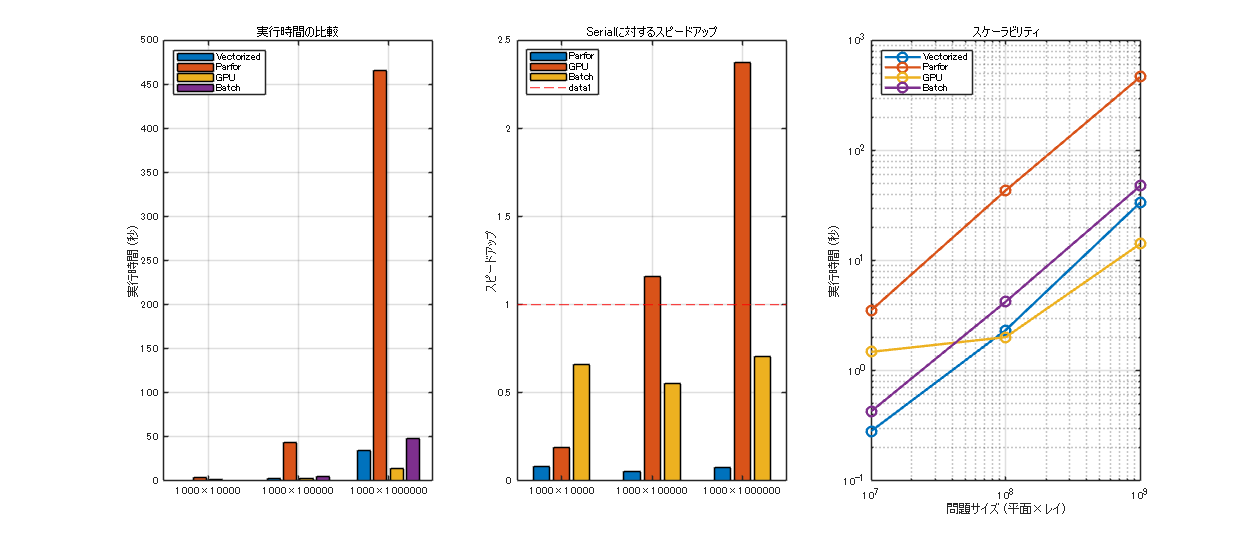

% グラフ表示
figure('Position', [100, 100, 1400, 600]);

% 実行時間の比較
subplot(1, 3, 1);
validResults = results(:, validMethods);
validMethodNames = methods(validMethods);
bar(validResults);
set(gca, 'XTickLabel', arrayfun(@(p, r) sprintf('%d×%d', p, r), ...
    planesList, raysList, 'UniformOutput', false));
ylabel('実行時間 (秒)');
title('実行時間の比較');
legend(validMethodNames, 'Location', 'northwest');
grid on;

% スピードアップの比較
if validMethods(1)
    subplot(1, 3, 2);
    speedups = results(:, 1) ./ results(:, validMethods);
    speedups(:, 1) = [];  % Serial自身を除外
    bar(speedups);
    set(gca, 'XTickLabel', arrayfun(@(p, r) sprintf('%d×%d', p, r), ...
        planesList, raysList, 'UniformOutput', false));
    ylabel('スピードアップ');
    title('Serialに対するスピードアップ');
    legend(validMethodNames(2:end), 'Location', 'best');
    yline(1, '--r', 'LineWidth', 1);
    grid on;
end

% 問題サイズ vs 実行時間（対数スケール）
subplot(1, 3, 3);
problemSizes = planesList .* raysList;
for j = 1:length(methods)
    if validMethods(j)
        loglog(problemSizes, results(:, j), 'o-', 'LineWidth', 2, ...
            'MarkerSize', 8, 'DisplayName', methods{j});
        hold on;
    end
end
xlabel('問題サイズ (平面×レイ)');
ylabel('実行時間 (秒)');
title('スケーラビリティ');
legend('Location', 'northwest');
grid on;


% 推奨事項
fprintf('\n==================================================================================\n');

fprintf('【推奨事項】\n');

【推奨事項】


fprintf('----------------------------------------------------------------------------------\n');

----------------------------------------------------------------------------------



% 問題サイズによる推奨
smallIdx = find(planesList .* raysList < 100000);
mediumIdx = find(planesList .* raysList >= 100000 & planesList .* raysList < 1000000);
largeIdx = find(planesList .* raysList >= 1000000);

if ~isempty(smallIdx)
    [~, bestMethod] = min(mean(results(smallIdx, :), 1, 'omitnan'));
    fprintf('小規模 (<100K tests): %s\n', methods{bestMethod});
end
if ~isempty(mediumIdx)
    [~, bestMethod] = min(mean(results(mediumIdx, :), 1, 'omitnan'));
    fprintf('中規模 (100K-1M tests): %s\n', methods{bestMethod});
end
if ~isempty(largeIdx)
    [~, bestMethod] = min(mean(results(largeIdx, :), 1, 'omitnan'));
    fprintf('大規模 (>1M tests): %s\n', methods{bestMethod});
end

大規模 (>1M tests): GPU



fprintf('\n==================================================================================\n');